clear all
clc
close all

x = linspace(-0.001,0.001,501);
[X,Y] = meshgrid(x,x);
[phi,r] = cart2pol(X,Y);

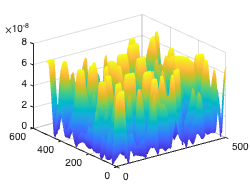

U = rand(501,501);
U1 = fft2(U);
fil = r < 0.00003;   % 0.005 mm
U2 = fil .* U1 ;
U3 = ifftshift(ifft2(U2));
U4 = abs(U3);
% % mesh(U4)
U5 = U4 ./ max(U4);
% % mesh(U5)
U6 = 70 .* 10^(-9) .* U5;
mesh(U6)

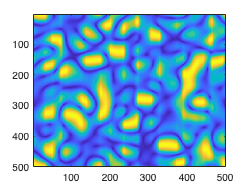

imagesc(U6)

randomSurf = U6;

%rs = load("randomSurf", "U6");
%rs = rs.U6;
%delta = rs

lambda = 633e-9; 
k = 2.*pi./lambda; 

% Model Parameters
 l = input("Enter l value: ");         % topological charge;
 n =  input("Enter n value: ");	% radial index; n=|l|,|l|+2,|l|+4 ...
 D =  sqrt(2);   % is a constant for normalization;


Z=0.6; %[-] a XY-slice in the z-direction


% Analytical functions
gauss = @(r,z) exp(-r.^2./(1+z.^2));
G = @(r,z) D./sqrt(1+z.^2).*exp(-r.^2./(1+z.^2)).*exp(-1i/4*(z.*r.^2)./(1+z.^2));
A = @(r,Z) (sqrt(2)*r./sqrt(1+Z.^2)).^abs(l).*LaguerreL((n-abs(l))/2,abs(l),2*r.^2./(1+Z.^2));
PHI = @(th) exp(1i*l*th);
PHIM = @(th) exp(1i*-l*th);
PSI = @(z) exp(-1i*(n+1)*atan(z));
P =  G(r,Z).*A(r,Z).*PHI(phi).*PSI(Z).*exp(-1i*0);%.*exp(1i*2*k.*gauss);
PM = G(r,Z).*A(r,Z).*PHIM(phi).*PSI(Z).*exp(-1i*0);
S = P+PM.*gauss(r,Z);

% Compute profile for a seleted time 't':
%p1=P(phi,r,Z,0);

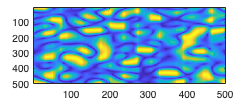


% Plot a single slice of the presure profile
figure(1); fontsize=12;
%set(gcf,'position',[100,100,600,200])
set(gcf,'position',[50,50,500,200])

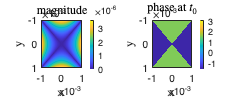

subplot(121), imagesc(x,x,flipud(abs(S))); colorbar;
% xlim([-10,10]);
% ylim([-10,10])
xlabel('x','interpreter','latex','fontsize',fontsize);
ylabel('y','interpreter','latex','fontsize',fontsize);
title('magnitude','interpreter','latex','fontsize',fontsize);
subplot(122), imagesc(x,x,flipud(angle(S))); colorbar;
xlabel('x','interpreter','latex','fontsize',fontsize);
ylabel('y','interpreter','latex','fontsize',fontsize);
title('phase at $t_0$','interpreter','latex','fontsize',fontsize);

function v = LaguerreL(varargin)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         Plot Generalized Legendre Polynomials: LaguerreL(n,z)
%
%               Coded by Manuel Diaz, NHRI, 2018.08.28.
%                   Copyright (c) 2018, Manuel Diaz.
%                           All rights reserved.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Refs.:
% [1] Milton Abramowitz, Irene Stegun, Handbook of Mathematical Functions,
%     National Bureau of Standards, 1964, ISBN: 0-486-61272-4, LC:QA47.A34.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Evaluates the Generalized Laguerre polynomials GL(n,k,x).
%
%  First terms:
%
%    GL(0,k,x) = 1;
%    GL(1,k,x) = 1 + k - x;
%    GL(2,k,x) = 2 + 3*k + k^2 - 4*x - 2*k*x + x^2)/2;
%    GL(3,k,x) = 6 + 11*k + 6*k^2 + k^3 - 18*x - 15*k*x - 3*k^2*x + ...
%                  9*x^2 + 3*k*x^2 - x^3)/6.
%  Recursion:
%
%    GL(0,k,X) = 1 
%    GL(1,k,X) = 1 + k - x;
%
%    if 2 <= a:
%
%    GL(n,k,X) = ( (k+2*n-1-X) * GL(n-1,k,X) + (1-k-n) * GL(n-2,k,X) ) / n
%
%  Special values:
%
%    For k = 0, the associated Laguerre polynomials GL(N,K,X) are equal 
%    to the Laguerre polynomials L(N,X).
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This program and its subprograms may be freely used, modified and
% distributed under the GNU General Public License: 
% http://www.gnu.org/copyleft/gpl.html   
%
% Basic Assumptions:
% n: is a positive interger value.
% k: is a positive interger value.
% k: can be a single value or vector array.   
%
% Function inputs:
if (nargin == 2)     % Evaluate classical Laguerre Polynomials
    n=varargin{1};
    k=0;
    x=varargin{2};
elseif (nargin == 3) % Evaluate generalized Laguerre Polynomials
    n=varargin{1};
    k=varargin{2};
    x=varargin{3};
else 
    error('Usage: >> LaguerreL(n:int,k:int,x:array)');
end

% Verify inputs
if rem(n,1)~=0, error('n must be an integer.'); end
if rem(k,1)~=0, error('k must be an integer.'); end
if n < 0, error('n must be positive integer.'); end
if k < 0, error('k must be positive integer.'); end

% Initialize solution array
v = zeros(size(x));

% Compute Laguerre Polynomials
GL = zeros( numel(x), n+1 );
if n==0
    v(:) = 1.0;         % GL(0,k,x)
elseif n==1
    v(:) = 1+k-x(:);    % GL(1,k,x)
elseif n>1
    GL(:,1) = 1;        % GL(0,k,x)
    GL(:,2) = 1+k-x(:); % GL(1,k,x)
    for i = 2:n
        GL(:,i+1) = ( (k+2*i-1-x(:)).*GL(:,i) + (-k-i+1).*GL(:,i-1) )/i;
    end
    v(:) = GL(:,i+1);   % GL(n,k,x)
end
end